# Natural Resources Management

# Final Project

addpath("utils\")

## Part 0. Data pre-processing

file = readmatrix("data\5. Jochenstein.csv");
data_precipitation = file(:,4); % [mm/d]
data_streamflow = file(:,5); % [m3/s]
data_temperature = file(:,6); % °C

### Dataset times

Total dataset total years and years used for training, taking 70% of the dataset

T = 365;
tr_length = 0.70;
years_total = length(file) / T

years_total = 27

years_tr = floor(years_total*tr_length)

years_tr = 18

### Dataset partition 

% Training dataset
x_tr = data_streamflow(1:T*years_tr);
u_tr = [data_precipitation(1:T*years_tr) data_temperature(1:T*years_tr)];
% Validation dataset
x_val = data_streamflow(T*years_tr+1:end);
u_val = [data_precipitation(T*years_tr+1:end) data_temperature(T*years_tr+1:end)];

### Cyclostationary  analysis

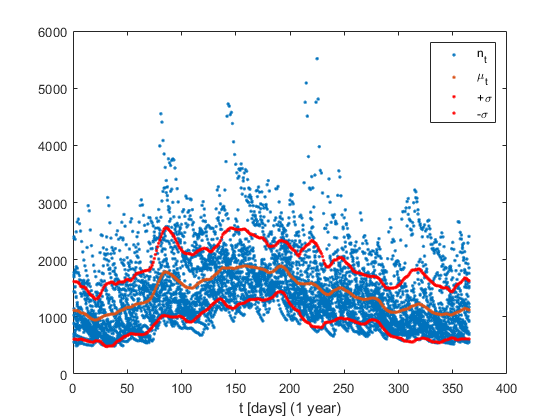

f = 5; 
N_tr = length(x_tr);
tt = repmat([1:T]', N_tr/T, 1);
% Moving Average
[mi, m] = moving_average(x_tr, T, f);
% Moving variance
[ma_var2, s2] = moving_average((x_tr - m).^2, T, f);
ma_var = ma_var2.^(1/2);
s = s2.^(1/2);
figure;
plot(tt, [x_tr, m], '.');
xlabel('t [days] (1 year)');
hold on;
% plot([1 : T], mi, 'g', 'LineWidth',.5);
plot(tt, m + s, '.r');
plot(tt, m - s, '.r');
legend('n_t', '\mu_t', '+\sigma', '-\sigma');

% legend('n_t', '\mu_t', '\mu_{cyclo}', '+\sigma', '-\sigma');

### Correlations

#### Streamflow - Precipitations

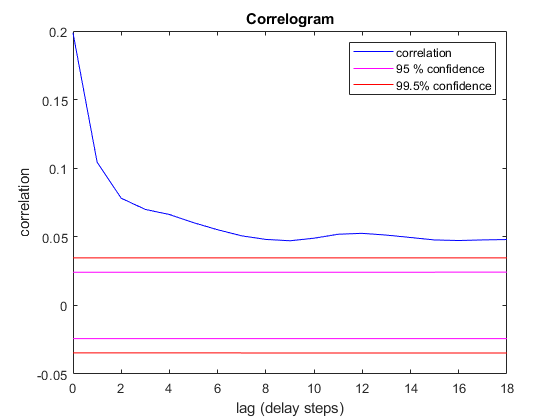

figure; correlogram(x_tr, u_tr(:,1), years_tr)

#### Streamflow - Temperature

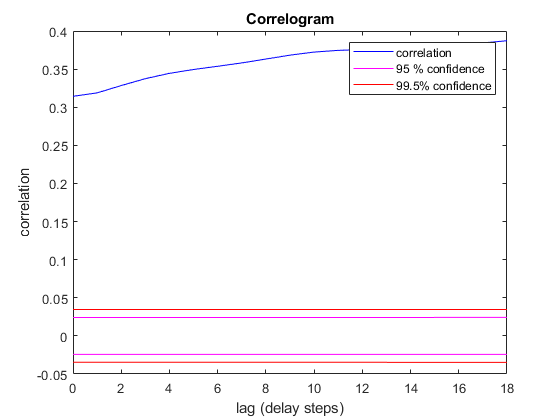

figure; correlogram(x_tr, u_tr(:,2), years_tr)

### Data normalization

f = 5; 
[x_norm, mean_x, sigma_x] = deseasonalize(x_tr, T, f);
[u_norm(:,1), mean_u(:,1), sigma_u(:,1)] = deseasonalize(u_tr(:,1), T, f);
[u_norm(:,2), mean_u(:,2), sigma_u(:,2)] = deseasonalize(u_tr(:,2), T, f);

[x_norm_val, mean_x_val, sigma_x_val] = deseasonalize(x_val, T, f);
[u_norm_val(:,1), mean_u_val(:,1), sigma_u_val(:,1)] = deseasonalize(u_val(:,1), T, f);
[u_norm_val(:,2), mean_u_val(:,2), sigma_u_val(:,2)] = deseasonalize(u_val(:,2), T, f);

### Correlations

#### Streamflow - Precipitations

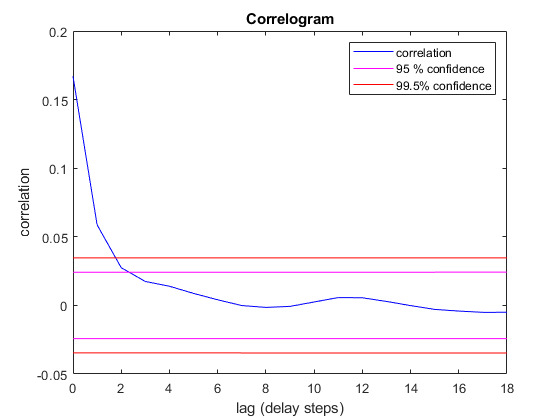

figure; correlogram(x_norm, u_norm(:,1), years_tr)

#### Streamflow - Temperature

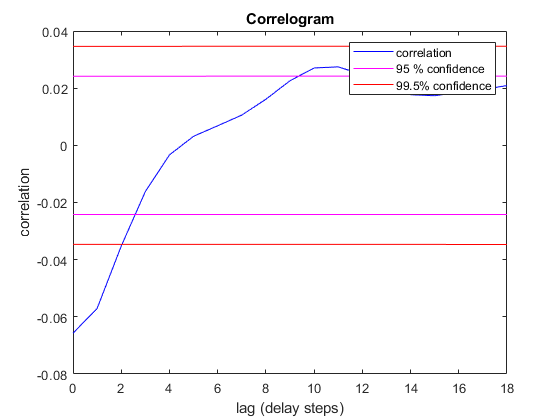

figure; correlogram(x_norm, u_norm(:,2), years_tr)

## Part 1. 1-day ahead forecast model

### Linear models

#### AR (n)

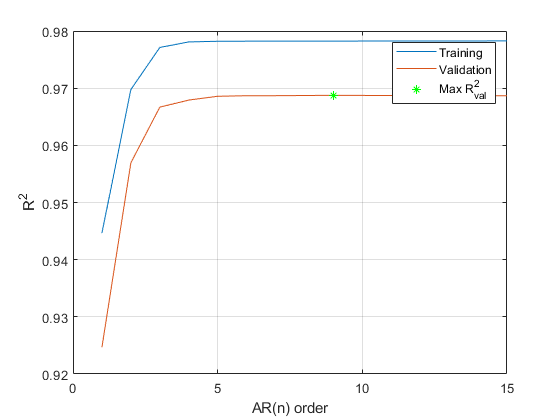

ar_iteation = 15;
r2_ar = nan(ar_iteation,1);
r2_ar_val = nan(ar_iteation,1);
r2_ar_val_max = 0;
ar_opt_idx = 0;
for i=1:ar_iteation
    [theta_ar_i, x_norm_ar] = trainAR(x_norm, i);
    x_norm_ar_val = estimateAR(x_norm_val, theta_ar_i, i);
    
%     Training
    r2_ar(i) = getR2Performance( ...
            x_tr, ...
            x_norm_ar, ...
            mean_x, ...
            sigma_x ...
        );
%     Validation
    r2_ar_val(i) = getR2Performance( ...
            x_val, ...
            x_norm_ar_val, ...
            mean_x_val, ...
            sigma_x_val ...
        );
    
    if r2_ar_val_max < r2_ar_val(i)
        theta_ar = theta_ar_i;
        ar_opt_idx = i;
        r2_ar_val_max = r2_ar_val(i);
    end
    
end
clear i
figure;
plot([r2_ar, r2_ar_val])
hold on 
plot (ar_opt_idx, r2_ar_val_max, '*g')
legend('Training','Validation','Max R^2_{val}')
xlabel('AR(n) order');ylabel('R^2');
grid on

#### Proper ARX (1,1)

y = x_norm(2:end);
M = [x_norm(1:end-1), u_norm(1:end-1,:)];
theta = M\y;
x_est = [x_norm(1); M*theta];
r2_arx = getR2Performance(x_tr, x_est, mean_x, sigma_x)

r2_arx = 0.9708

M_val = [x_norm_val(1:end-1), u_norm_val(1:end-1,:)];
x_est = [x_norm_val(1); M_val*theta];
r2_arx_val = getR2Performance(x_val, x_est, mean_x_val, sigma_x_val)

r2_arx_val = 0.9626

#### Improper ARX (1,1)

y = x_norm(2:end);
M = [x_norm(1:end-1), u_norm(2:end,:)];
theta = M\y;
x_est = [x_norm(1); M*theta];
r2_arx_imp = getR2Performance(x_tr, x_est, mean_x, sigma_x)

r2_arx_imp = 0.9563

M_val = [x_norm_val(1:end-1), u_norm_val(1:end-1,:)];
x_est = [x_norm_val(1); M_val*theta];
r2_arx_imp_val = getR2Performance(x_val, x_est, mean_x_val, sigma_x_val)

r2_arx_imp_val = 0.9545

### Nonlinear models

#### Proper ANN

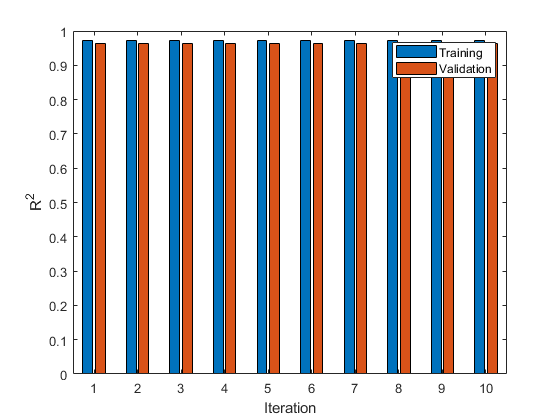

% Train dataset
x_ann = [x_norm(1:end-1), u_norm(1:end-1,:)]';
y_ann = x_norm(2:end)';
% Validation dataset
x_ann_val = [x_norm_val(1:end-1) u_norm_val(1:end-1,:)]';

N_runs = 10;
r2_ann_prop = zeros(N_runs, 1);
r2_ann_prop_val = zeros(N_runs, 1);
ann_opt_idx = 0;
for i = 1:N_runs
    % ANN Train
    ann_prop_i = feedforwardnet(3);
    ann_prop_i = train(ann_prop_i,x_ann,y_ann);
    
    % view(ann_prop)
    y = ann_prop_i(x_ann);
    y_ann_prop = [x_norm(1); y'];
    r2_ann_prop(i) = getR2Performance(x_tr, y_ann_prop, mean_x, sigma_x);
    
    % Validation
    y = ann_prop_i(x_ann_val);
    y_ann_prop_val = [x_norm_val(1); y'];
    r2_ann_prop_val(i) = getR2Performance(x_val, y_ann_prop_val, mean_x_val, sigma_x_val);
    
    
    if r2_ann_prop_val(i) >= max(r2_ann_prop_val)
        ann_prop = ann_prop_i; % Optimal ANN wrt validation dataset
        ann_opt_idx = i;
    end
    
end

figure; 
h = bar([r2_ann_prop, r2_ann_prop_val]);
set(h, {'DisplayName'}, {'Training','Validation'}')
xlabel('Iteration');ylabel('R^2');
legend()

#### Improper ANN

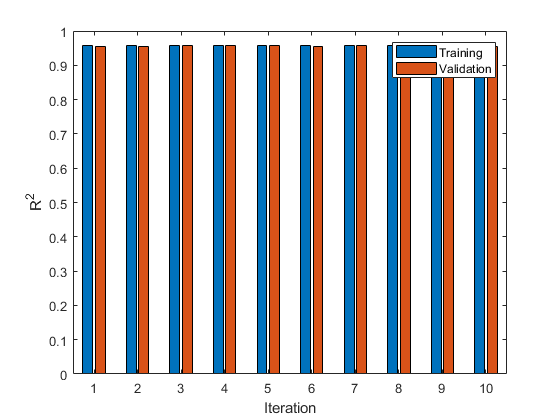

% Train dataset
x_ann = [x_norm(1:end-1), u_norm(2:end,:)]';
y_ann = x_norm(2:end)';
% Validation dataset
x_ann_val = [x_norm_val(1:end-1) u_norm_val(1:end-1,:)]';

N_runs = 10;
r2_ann_improp = zeros(N_runs, 1);
r2_ann_improp_val = zeros(N_runs, 1);
ann_improp_opt_idx = 0;
for i = 1:N_runs
    % ANN Train
    ann_improp_i = feedforwardnet(3);
    ann_improp_i = train(ann_improp_i,x_ann,y_ann);
    
    % view(ann_prop)
    y = ann_improp_i(x_ann);
    y_ann_improp = [x_norm(1); y'];
    r2_ann_improp(i) = getR2Performance(x_tr, y_ann_improp, mean_x, sigma_x);
    
    % Validation
    y = ann_improp_i(x_ann_val);
    y_ann_improp_val = [x_norm_val(1); y'];
    r2_ann_improp_val(i) = getR2Performance(x_val, y_ann_improp_val, mean_x_val, sigma_x_val);
    
    
    if r2_ann_improp_val(i) >= max(r2_ann_improp_val)
        ann_improp = ann_improp_i; % Optimal ANN wrt validation dataset
        ann_improp_opt_idx = i;
    end
    
end

figure; 
h = bar([r2_ann_improp, r2_ann_improp_val]);
set(h, {'DisplayName'}, {'Training','Validation'}')
xlabel('Iteration');ylabel('R^2');
legend()

#### CART

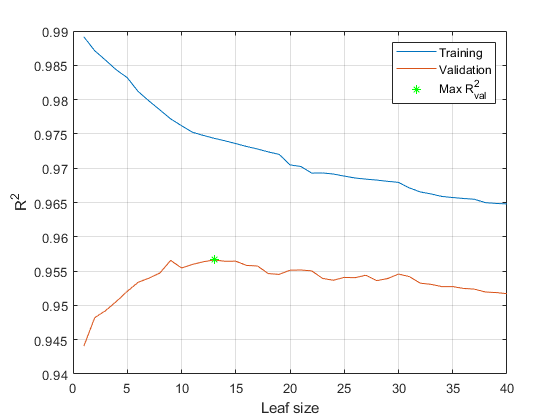

x_cart = [x_norm(1:end-1), u_norm(1:end-1,:)];
y_cart = x_norm(2:end);

x_cart_val = [x_norm_val(1:end-1), u_norm_val(1:end-1,:)];
y_cart_val = x_norm_val(2:end);
    
max_leaf_size = 40;
r2_cart = zeros(max_leaf_size,1);
r2_cart_val = zeros(max_leaf_size,1);
leafsize_opt = 0;

for i = 1:max_leaf_size
    T_i = fitrtree(x_cart, y_cart,'MinLeafSize',i);
    % view(T, 'mode', 'graph');
    y = predict(T_i, x_cart);
    y_cart_predict = [x_norm(1); y];
    r2_cart(i) = getR2Performance(x_tr, y_cart_predict, mean_x, sigma_x);
    
%     Validation
    y = predict(T_i, x_cart_val);
    y_cart_predict_val = [x_norm_val(1); y];
    r2_cart_val(i) = getR2Performance(x_val, y_cart_predict_val, mean_x_val, sigma_x_val);
    
    if r2_cart_val(i) >= max(r2_cart_val)
        T_opt = T_i; % Optimal ANN wrt validation dataset
        leafsize_opt = i;
    end 
end

figure;
plot([r2_cart, r2_cart_val])
hold on
plot (leafsize_opt, r2_cart_val(leafsize_opt), '*g')
legend('Training','Validation','Max R^2_{val}')
xlabel('Leaf size');ylabel('R^2');
grid on

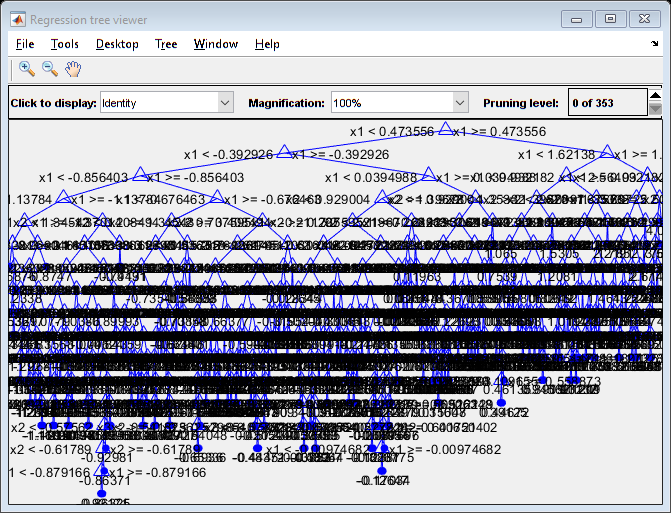

view(T_opt,'mode','graph')

T_opt.NumNodes

ans = 787

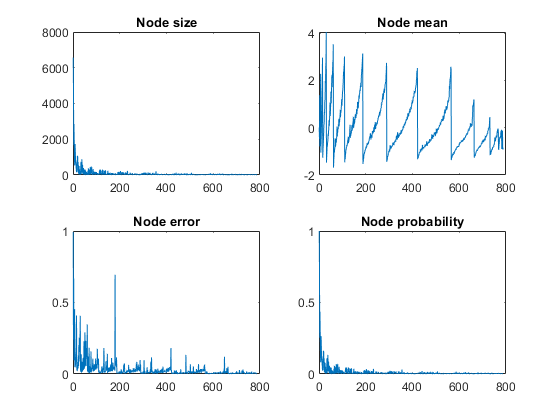

figure
subplot(2,2,1); plot( T_opt.NodeSize ); title('Node size'); % number of samples per node
subplot(2,2,2); plot( T_opt.NodeMean ); title('Node mean'); % mean samples in each node
subplot(2,2,3); plot( T_opt.NodeError ); title('Node error'); % node error
subplot(2,2,4); plot( T_opt.NodeProbability); title('Node probability')

|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |    0.042238 |      1.8311 |    0.042238 |    0.042238 |            4 |


|    2 | Accept |    0.060075 |     0.31564 |    0.042238 |    0.043431 |          149 |


|    3 | Best   |    0.040303 |     0.25967 |    0.040303 |    0.044243 |           26 |


|    4 | Accept |     0.22704 |    0.087396 |    0.040303 |    0.040303 |         1402 |


|    5 | Accept |    0.048138 |     0.83909 |    0.040303 |    0.040296 |            1 |


|    6 | Accept |    0.046832 |     0.13401 |    0.040303 |    0.040502 |           54 |


|    7 | Best   |    0.039773 |     0.16684 |    0.039773 |    0.039714 |           14 |


|    8 | Best   |    0.039604 |     0.10372 |    0.039604 |    0.039553 |           19 |


|    9 | Best   |    0.039291 |     0.13165 |    0.039291 |     0.03944 |           18 |


|   10 | Accept |    0.039291 |     0.10334 |    0.039291 |    0.039399 |           18 |


|   11 | Accept |    0.039291 |     0.10604 |    0.039291 |    0.039376 |           18 |


|   12 | Accept |     0.68939 |    0.093454 |    0.039291 |    0.039384 |         3284 |


|   13 | Accept |     0.10244 |    0.064409 |    0.039291 |    0.039358 |          480 |


|   14 | Accept |    0.045341 |     0.39723 |    0.039291 |    0.039366 |            2 |


|   15 | Accept |    0.039412 |     0.23189 |    0.039291 |    0.039386 |            9 |


|   16 | Accept |    0.039975 |     0.18573 |    0.039291 |    0.039389 |            7 |


|   17 | Accept |    0.039831 |      0.2016 |    0.039291 |    0.039389 |           12 |


|   18 | Accept |    0.039965 |     0.11248 |    0.039291 |    0.039445 |           21 |


|   19 | Accept |    0.039605 |     0.10797 |    0.039291 |    0.039461 |           16 |


|   20 | Accept |     0.19057 |    0.097432 |    0.039291 |     0.03939 |          746 |


|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|   21 | Accept |    0.082375 |    0.066616 |    0.039291 |    0.039388 |          284 |


|   22 | Accept |    0.051914 |     0.10464 |    0.039291 |    0.039386 |           82 |


|   23 | Accept |    0.043198 |     0.19865 |    0.039291 |    0.039395 |           37 |


|   24 | Accept |     0.04365 |     0.43336 |    0.039291 |    0.039397 |            3 |


|   25 | Accept |    0.039876 |     0.13938 |    0.039291 |    0.039398 |           10 |


|   26 | Accept |    0.041198 |     0.26929 |    0.039291 |      0.0394 |            6 |


|   27 | Accept |     0.03982 |      0.2493 |    0.039291 |    0.039399 |            8 |


|   28 | Accept |    0.039605 |     0.19193 |    0.039291 |    0.039411 |           16 |


|   29 | Accept |    0.040557 |     0.18914 |    0.039291 |    0.039411 |           22 |


|   30 | Accept |     0.33827 |    0.064391 |    0.039291 |    0.039424 |         2105 |


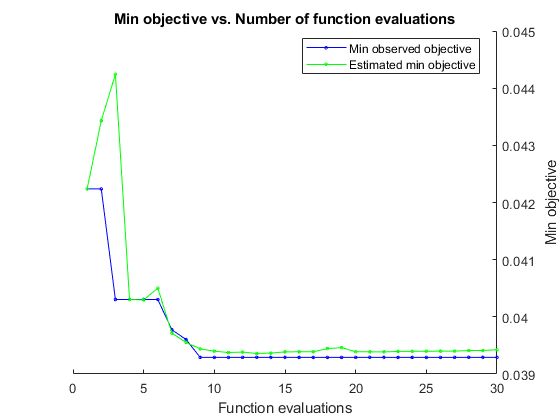

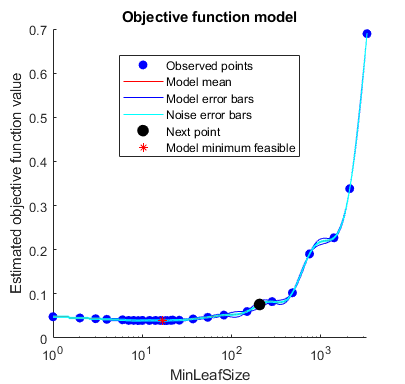


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 52.6785 seconds.
Total objective function evaluation time: 7.4774

Best observed feasible point:
    MinLeafSize
    ___________

        18     

Observed objective function value = 0.039291
Estimated objective function value = 0.039424
Function evaluation time = 0.13165

Best estimated feasible point (according to models):
    MinLeafSize
    ___________

        18     

Estimated objective function value = 0.039424
Estimated function evaluation time = 0.14545



T_opt_auto = fitrtree(x_cart, y_cart,'OptimizeHyperparameters','auto');

y = predict(T_opt_auto, x_cart_val);
y_cart_predict_val = [x_norm_val(1); y];
r2_cart_auto_val = getR2Performance(x_val, y_cart_predict_val, mean_x_val, sigma_x_val)

r2_cart_auto_val = 0.9546

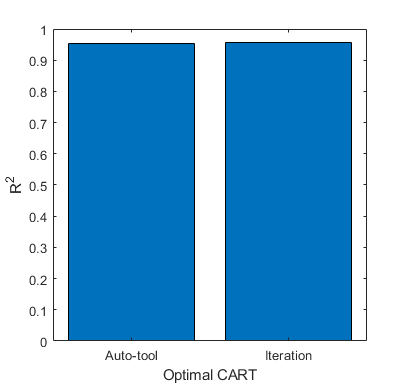

c = categorical({'Iteration','Auto-tool'});
bar(c, [max(r2_cart_val); r2_cart_auto_val])
xlabel('Optimal CART');ylabel('R^2');

### Models comparison

figure;
c = categorical({ ...
    'AR(1)', ...
    'AR(opt)', ...
    'ARX(1,1) Proper', ...
    'ARX(1,1) Improper', ...
    'ANN(3) Proper', ...
    'ANN(3) Improper', ...
    'CART', ...
    });
r2_index = [ ...
    r2_ar(1), r2_ar_val(1); ...
    r2_ar(ar_opt_idx), r2_ar_val(ar_opt_idx); ...
    r2_arx, r2_arx_val; ...
    r2_arx_imp, r2_arx_imp_val; ...
    r2_ann_prop(ann_opt_idx), r2_ann_prop_val(ann_opt_idx); ...
    r2_ann_improp(ann_improp_opt_idx), r2_ann_improp_val(ann_improp_opt_idx); ...
    r2_cart(leafsize_opt), r2_cart_val(leafsize_opt); ...
    ]

r2_index =     0.9446    0.9247
    0.9782    0.9688
    0.9708    0.9626
    0.9563    0.9545
    0.9729    0.9647
    0.9576    0.9577
    0.9744    0.9566


latex(sym(r2_index))

ans = '\left(\begin{array}{cc} \frac{4254303866977999}{4503599627370496} & \frac{8328844222052847}{9007199254740992}\\ \frac{8811136698331363}{9007199254740992} & \frac{8725727445702229}{9007199254740992}\\ \frac{8744264633828013}{9007199254740992} & \frac{4335054481255795}{4503599627370496}\\ \frac{8613840341972627}{9007199254740992} & \frac{4298466707627795}{4503599627370496}\\ \frac{8763093870313797}{9007199254740992} & \frac{8689679385386395}{9007199254740992}\\ \frac{4312765145356439}{4503599627370496} & \frac{8626073228057547}{9007199254740992}\\ \frac{8776274220973427}{9007199254740992} & \frac{538533697636593}{562949953421312} \end{array}\right)'

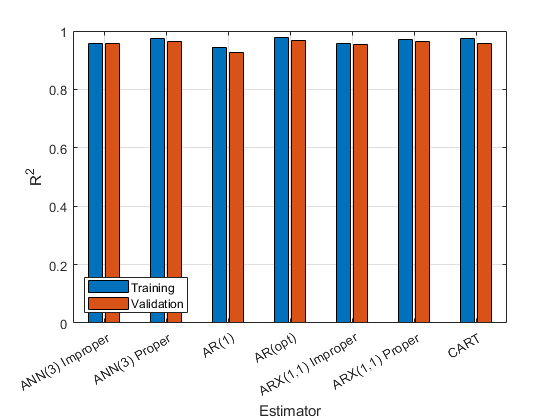

h = bar(c,r2_index);
set(h, {'DisplayName'}, {'Training','Validation'}')
xlabel('Estimator');ylabel('R^2');
legend("Location","southwest")
grid on

## Part 2. Damming policies

### Dam sizing

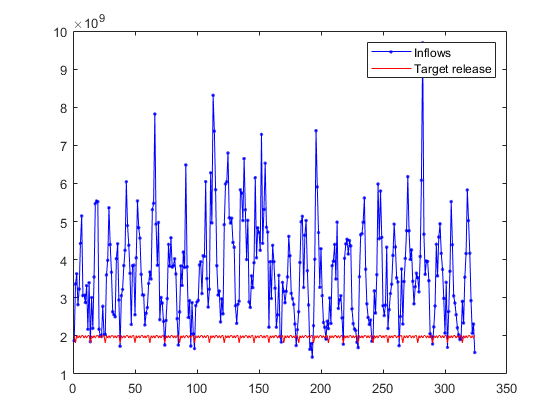

% years_total = 27;
lake_surface = 76984.120000e6; % [m2]
Q_month = dailyToMonthly(data_streamflow, years_total);
w = 750; % [m3/s] Target release - Downstrem demand 
deltaT = 3600*24*[31 28 31 30 31 30 31 31 30 31 30 31]';
Q = Q_month(:).*repmat(deltaT,years_total,1) ; % [m3/month]
W = w*ones(size(Q)).*repmat(deltaT,years_total,1) ; % [m3/month]

figure;
plot(Q, '.-b'); hold on
plot(W, 'r');
legend('Inflows', 'Target release')

#### Rippl criteria

[rippl] = abs(getRipple(W,Q));
rippl/lake_surface

ans = 0.0017

#### Sequent Peak Analysis criteria

[spa, K] = getSPA(W,Q);
spa/lake_surface

ans = 0.0139

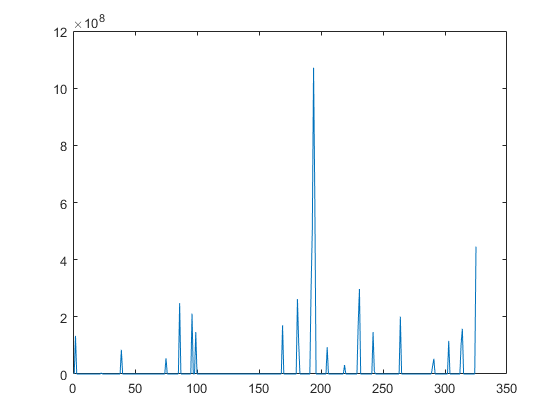

figure;
plot(K)

### Define Standard Operating policy

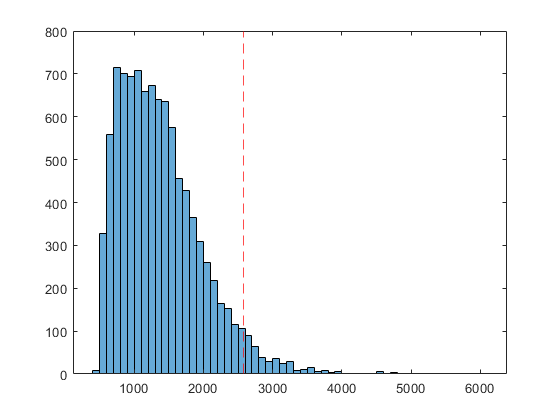

% max_nat_release_est = 3000;
max_nat_release_est = mean(data_streamflow) + 2*std(data_streamflow); % [m3/s]
figure;
histogram(data_streamflow)
hold on;
xline(max_nat_release_est,'--r');

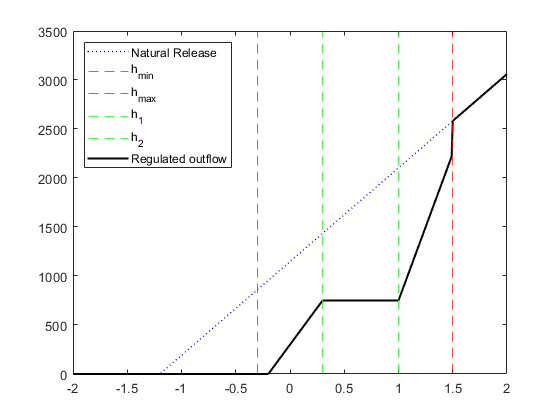

param.reg.w = w;
param.reg.hmin = -0.3;
param.reg.hmax = 1.5;

param.nat.S = lake_surface;
param.nat.h0 = -1.2; % TODO: Check this param
% Add equation
param.nat.m = max_nat_release_est/(param.reg.hmax - param.nat.h0);
param.nat.b = -param.nat.m*param.nat.h0;

param.reg.h1 = 0.3;
param.reg.h2 = 1;

param.reg.m1 = 1500;
param.reg.m2 = 3000;

h_test = -2:0.01:2;
r_test = zeros(size(h_test));
idx = find(h_test>param.nat.h0);
r_test(idx) = param.nat.m*h_test(idx) + param.nat.b;

r_reg = getRegulatedReleaseSimplified(h_test, param);

figure;
plot(h_test, r_test, ':b','LineWidth',1)
hold on;
xline(param.reg.hmin,'--r');
xline(param.reg.hmax,'--r');

xline(param.reg.h1,'--g');
xline(param.reg.h2,'--g');

plot(h_test, r_reg,'k','LineWidth',1.5)
legend('Natural Release', 'h_{min}', 'h_{max}', 'h_1', 'h_2','Regulated outflow','Location','northwest')